% Paths relativos según tu estructura
validationDir = './Images';              % Carpeta de imágenes a validar (dentro de Validation-Dataset)
outputDir     = './ValidationMasks';     % Carpeta de máscaras generadas
idealDir      = './Masks-Ideal';         % Carpeta de máscaras ideales para comparar




% Crear carpeta de output si no existe
if ~exist(outputDir, 'dir')
    mkdir(outputDir);
end

% Cargar el modelo entrenado desde el set de entrenamiento (ruta absoluta o relativa)
load('MATLAB Drive/Programacio1/Training-Dataset/Training-Dataset/pell.mat'); % Ajusta el path si es necesario
umbral = 26000; % Pon tu umbral óptimo

% --- 1) Segmentar todas las imágenes ---
validationFiles = dir(fullfile(validationDir, '*.jpg')); % Cambia a 'png' o lo que uses

for k = 1:length(validationFiles)
    img = imread(fullfile(validationDir, validationFiles(k).name));
    BW_piel = algo2(img, hist_2d, Cb_edges, Cr_edges, umbral);
    BW_piel = ~BW_piel;
    [~, baseName, ~] = fileparts(validationFiles(k).name);
    maskName = [baseName '.bmp'];
    imwrite(BW_piel, fullfile(outputDir, maskName));
end

disp('¡Todas las segmentaciones de Validation están guardadas en ValidationMasks!');

¡Todas las segmentaciones de Validation están guardadas en ValidationMasks!


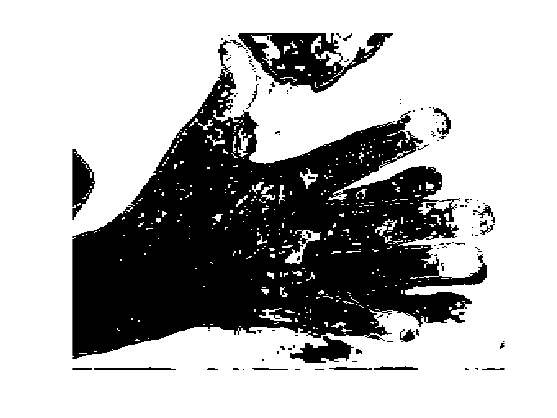


% --- 2) Evaluar con las máscaras ideales ---
maskFiles = dir(fullfile(outputDir, '*.bmp'));
F_scores = zeros(length(maskFiles),1);
precision_vals = zeros(length(maskFiles),1);
recall_vals = zeros(length(maskFiles),1);

for k = 1:length(maskFiles)
    mask_name = maskFiles(k).name;
    mask = imread(fullfile(outputDir, mask_name)) > 0;
    ideal_path = fullfile(idealDir, mask_name);
    if ~exist(ideal_path, 'file')
        warning('Máscara ideal %s no existe', mask_name); continue;
    end
    ideal = imread(ideal_path) > 0;
    %mask = ~mask
    % Si tu BW es invertida usa: mask = ~mask; ideal = ~ideal;
    if ~isequal(size(mask), size(ideal))
        warning('Dimensión inconsistente en %s', mask_name); continue;
    end
    TP = sum(mask(:) & ideal(:));
    FP = sum(mask(:) & ~ideal(:));
    FN = sum(~mask(:) & ideal(:));

     if (TP+FP)==0
        precision = NaN;
    else
        precision = TP / (TP + FP);
    end

    if (TP+FN)==0
        recall = NaN;
    else
        recall = TP / (TP + FN);
    end

    if isnan(precision) || isnan(recall) || (precision+recall)==0
        F = NaN;
    else
        F = 2 * precision * recall / (precision + recall);
    end

    precision_vals(k) = precision;
    recall_vals(k) = recall;
    F_scores(k) = F;
end
% Comprobacion de una sola mascara
mask = imread('ValidationMasks/5_P_hgr1_id04_2.bmp'); 
ideal = imread('Masks-Ideal/5_P_hgr1_id04_2.bmp');
imshow(~mask);

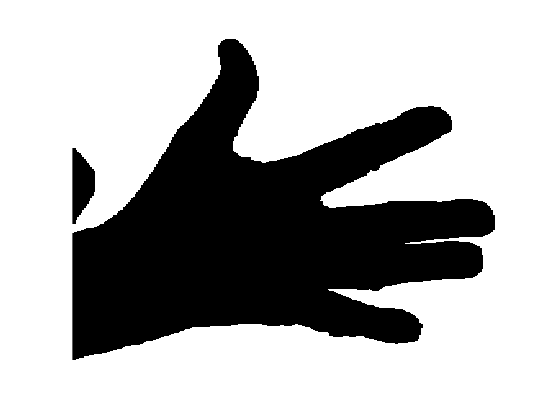

imshow(ideal);

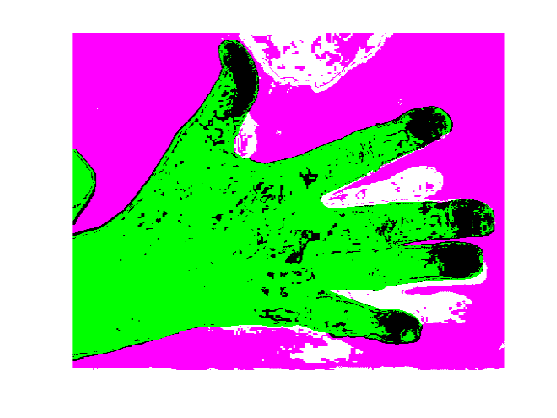

imshowpair(mask, ideal)


fprintf('F-score medio: %.3f\n', nanmean(F_scores));

F-score medio: 0.965


fprintf('Precisión media: %.3f\n', nanmean(precision_vals));

Precisión media: 0.948


fprintf('Recall media: %.3f\n', nanmean(recall_vals));

Recall media: 0.983


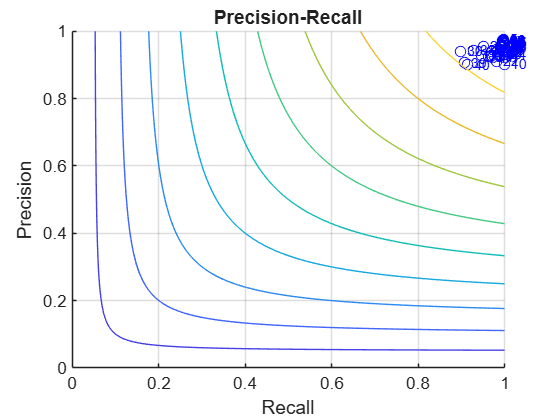


% Visualizar grafica resultante
% Definim els eixos de Recall i Precision
figure;
hold on;
recall = linspace(0, 1, 100);
precision = linspace(0, 1, 100);

plot(recall_vals, precision_vals, 'bo');

grid on;
xlim([0 1]);
ylim([0 1]);

% Añadir los números a cada punto, desplazados a la derecha
for k = 1:length(recall_vals)
    if ~isnan(recall_vals(k)) && ~isnan(precision_vals(k))
        text(recall_vals(k)+0.015, precision_vals(k), num2str(k), ...
            'FontSize',8, 'HorizontalAlignment','left', 'VerticalAlignment','middle', 'Color','b');
    end
end

% Creem una malla
[R, P] = meshgrid(recall, precision);

% Calculem el F-score per cada punt
F = 2 * (P .* R) ./ (P + R);
F(isnan(F)) = 0; % per evitar NaN quan P+R=0

% Dibuixem les línies de nivell de F-score

contour(R, P, F, 0:0.1:1);
xlabel('Recall');
ylabel('Precision');
title('Precision-Recall');




function BW_piel = algo2(imagenRGB, hist_2d, Cb_edges, Cr_edges, umbral)
    % imagenRGB: imagen de entrada (uint8, 3 canales)
    % hist_2d, Cb_edges, Cr_edges: tu modelo de piel (de algo1)
    % umbral: frecuencia mínima en el histograma para considerar piel

    imgYCbCr = rgb2ycbcr(imagenRGB);
    cb = double(imgYCbCr(:,:,2));
    cr = double(imgYCbCr(:,:,3));

    % A qué bin corresponde cada píxel
    bin_Cb = discretize(cb, Cb_edges); % Mapa de índices de Cb (por píxel)
    bin_Cr = discretize(cr, Cr_edges); % Mapa de índices de Cr (por píxel)

    % Sólo consideramos los índices válidos
    valid_mask = ~isnan(bin_Cb) & ~isnan(bin_Cr) & ...
                 bin_Cb > 0 & bin_Cr > 0 & ...
                 bin_Cb <= size(hist_2d,1) & bin_Cr <= size(hist_2d,2);

    % Índices lineales en el histograma
    ind = sub2ind(size(hist_2d), bin_Cb(valid_mask), bin_Cr(valid_mask));

    % Inicializa máscara
    BW_piel = false(size(cb));


    % Clasifica como piel si frecuencia en el histograma es mayor que el umbral
    BW_piel(valid_mask) = hist_2d(ind) > umbral;
  
end